## CISC271, Week 9, Day 1A: Cluster Iris Data

% Load the data and select the sepal measurements
load fisheriris.mat
xMat = meas(:, 3:4);
% Label 1 is Iris Vertosa; everything else is 0
yVec = strcmp(species, 'setosa');

% Use k-means for binary clustering
[yKmeans, gMat] = kmeans(xMat, 2, 'Replicates', 100);
% Select the lower left as Class 0
[~,classesNdx] = sort(gMat(:,1), 'ascend')

classesNdx =      2
     1


class1Ndx = classesNdx(1)

class1Ndx = 2

class0Ndx = classesNdx(2)

class0Ndx = 1

% Classes as 0 or 1
qVec = (yKmeans==class1Ndx);
% Midpoint of the centroids, as a vector
middleVec = mean(gMat)'

middleVec =     3.2087
    0.9723


% Direction from 0 to 1, as a vector
dir0to1 = (gMat(class1Ndx,:) - gMat(class0Ndx,:))'

dir0to1 =    -3.4331
   -1.4191


% Color map: red is class 0, blue is class 1
myCmap = [1 0 0 ; 0 0 1];
% Iris sepal data, by k-means
scatter(xMat(:,1),xMat(:,2),[],myCmap(qVec+1, :), 'filled');
axis('image');
axis([0 7 -1 3]);
% Add the k-means centroids and midpoint
hold on;
plot(gMat(:,1), gMat(:,2), 'kx', 'MarkerSize', 12, 'LineWidth', 3);
plot(middleVec(1), middleVec(2), 'kx', 'MarkerSize', 12, 'LineWidth', 3);
hold off;
% Add an arrow from the midpoint to Class 1 centroid
hold on;
quiver(middleVec(1),middleVec(2), dir0to1(1)/2,dir0to1(2)/2, 0,...
    'LineWidth',3, 'Color', 'k');
hold off;
% Midpoint is on the separating hyperplane and direction
% from centroid 0 to centroid 1 is a normal vector;
% compute the bias scalar 
bVal = -dir0to1'*middleVec

bVal = 12.3955

% Augmented vector is normal direction with bias scalar
wAug = [dir0to1 ; bVal]

wAug =    -3.4331
   -1.4191
   12.3955


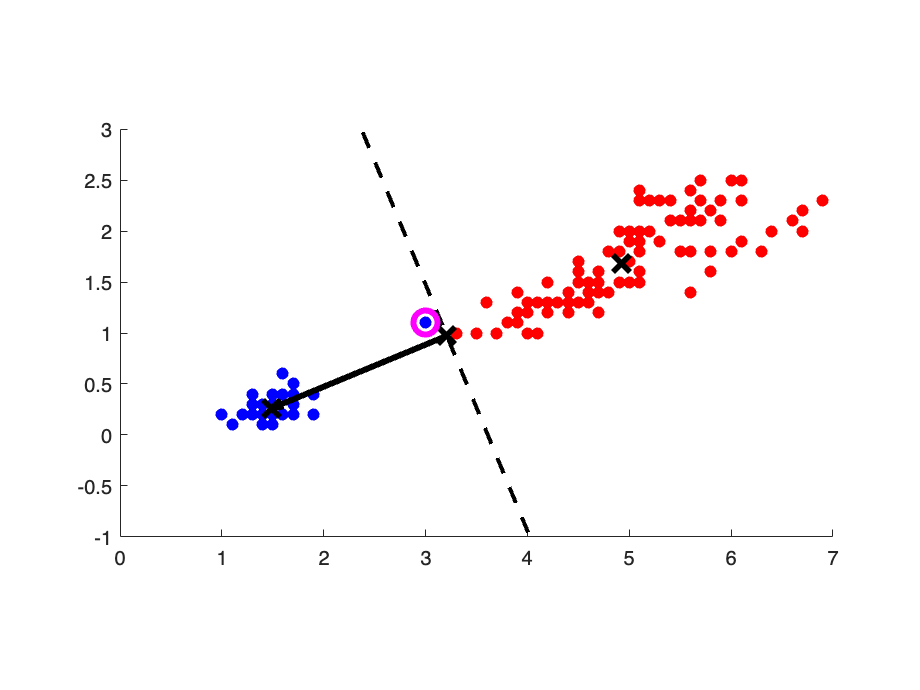

% Plot the separating hyperplane
plotline(wAug, 'k-');
% Save the relevant variables
save('week9Day1stuff', 'xMat', 'yVec', 'wAug', 'myCmap');
% Find misclassifications
missedVec = (yVec~=qVec);
% Circle the misclassified observations
hold on;
plot(xMat(missedVec,1), xMat(missedVec,2), 'mo', ...
    'MarkerSize', 12, 'LineWidth', 3);